clear
bass = matfile('data_bass.mat')

bass =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\matlab\data_bass.mat'
            Properties.Writable: false                                                                  
    Properties.ProtectedLoading: false                                                                  
                    circularity: [1x15 double]                                                          
                    compactness: [1x15 double]                                                          
                     elongation: [1x15 double]                                                          
                          holes: [1x15 double]                                                          
                      intensity: [1x15 double]                                                          
                        thiness: [1x15 double]                            

guitar = matfile('data_guitar.mat')

guitar =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\matlab\data_guitar.mat'
            Properties.Writable: false                                                                    
    Properties.ProtectedLoading: false                                                                    
                    circularity: [1x15 double]                                                            
                    compactness: [1x15 double]                                                            
                     elongation: [1x15 double]                                                            
                          holes: [1x15 double]                                                            
                      intensity: [1x15 double]                                                            
                        thiness: [1x15 double]          

trumpet = matfile('data_trumpet.mat')

trumpet =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\matlab\data_trumpet.mat'
            Properties.Writable: false                                                                     
    Properties.ProtectedLoading: false                                                                     
                    circularity: [1x15 double]                                                             
                    compactness: [1x15 double]                                                             
                     elongation: [1x15 double]                                                             
                          holes: [1x15 double]                                                             
                      intensity: [1x15 double]                                                             
                        thiness: [1x15 double] 

drumm = matfile('data_drumm.mat')

drumm =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\matlab\data_drumm.mat'
            Properties.Writable: false                                                                   
    Properties.ProtectedLoading: false                                                                   
                    circularity: [1x15 double]                                                           
                    compactness: [1x15 double]                                                           
                     elongation: [1x15 double]                                                           
                          holes: [1x15 double]                                                           
                      intensity: [1x15 double]                                                           
                        thiness: [1x15 double]                   

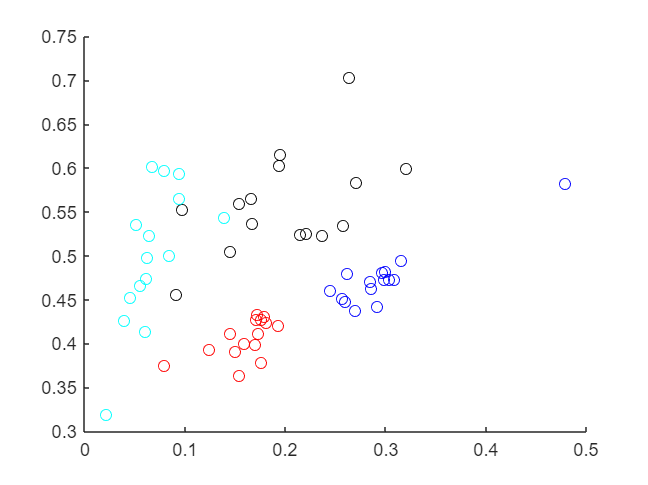


scatter(bass.circularity,bass.compactness,'red')
hold on
scatter(guitar.circularity,guitar.compactness,'blue')
scatter(trumpet.circularity,trumpet.compactness,'black')
scatter(drumm.circularity,drumm.compactness,'c')
hold off

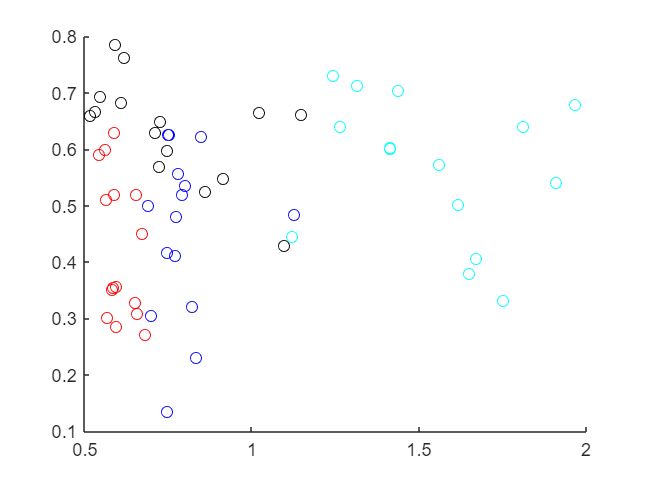


scatter(bass.elongation,bass.intensity,'red')
hold on
scatter(guitar.elongation,guitar.intensity,'blue')
scatter(trumpet.elongation,trumpet.intensity,'black')
scatter(drumm.elongation,drumm.intensity,'c')
hold off

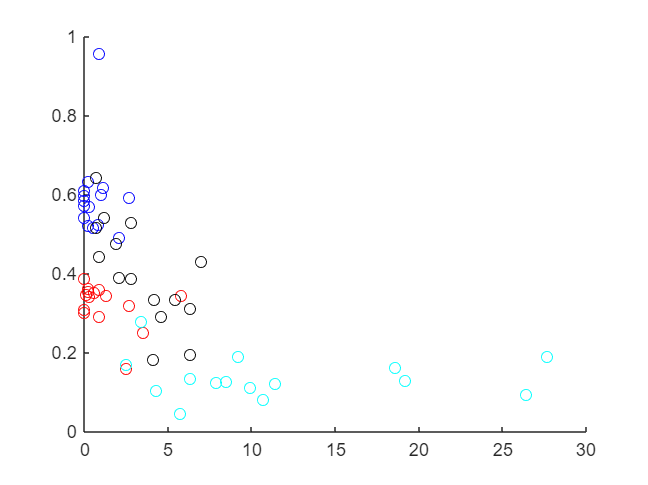


scatter(bass.holes,bass.thiness,'red')
hold on
scatter(guitar.holes,guitar.thiness,'blue')
scatter(trumpet.holes,trumpet.thiness,'black')
scatter(drumm.holes,drumm.thiness,'c')
hold off

Simple case

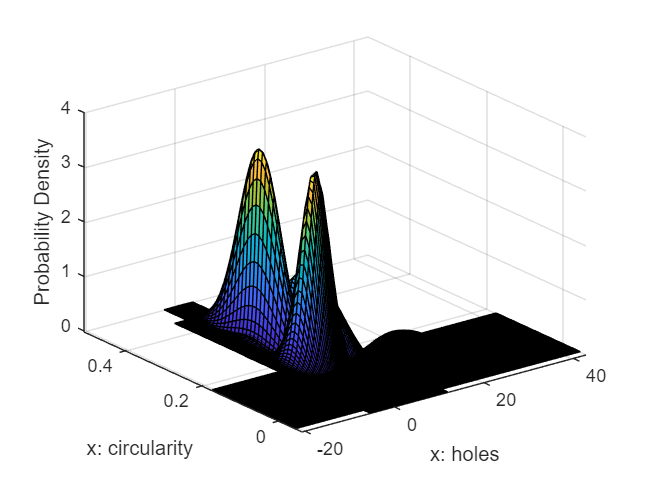

mu1 = mean([bass.holes', bass.circularity'])';
sigma1 = cov([bass.holes', bass.circularity']);
mu2 = mean([guitar.holes', guitar.circularity'])';
sigma2 = cov([guitar.holes', guitar.circularity']);

mu3 = mean([trumpet.holes', trumpet.circularity'])';
sigma3 = cov([trumpet.holes', trumpet.circularity']);

mu4 = mean([drumm.holes', drumm.circularity'])';
sigma4 = cov([drumm.holes', drumm.circularity']);


holesX1=[-4 *sqrt(sigma1(1,1))+mu1(1):0.2:4 *sqrt(sigma1(1,1))+mu1(1)];
holesY1=normpdf(holesX1,mu1(1),sqrt(sigma1(1,1)));
circX1=[-4 *sqrt(sigma1(2,2))+mu1(2):0.01:4*sqrt(sigma1(2,2))+mu1(2)];
circY1=normpdf(circX1,mu1(2),sqrt(sigma1(2,2)));

holesX2=[-4 *sqrt(sigma2(1,1))+mu2(1):0.2:4 *sqrt(sigma2(1,1))+mu2(1)];
holesY2=normpdf(holesX2,mu2(1),sqrt(sigma2(1,1)));
circX2=[-4 *sqrt(sigma2(2,2))+mu2(2):0.01:4*sqrt(sigma2(2,2))+mu2(2)];
circY2=normpdf(circX2,mu2(2),sqrt(sigma2(2,2)));

holesX3=[-4 *sqrt(sigma3(1,1))+mu3(1):0.2:4 *sqrt(sigma3(1,1))+mu3(1)];
holesY3=normpdf(holesX3,mu3(1),sqrt(sigma3(1,1)));
circX3=[-4 *sqrt(sigma3(2,2))+mu3(2):0.01:4*sqrt(sigma3(2,2))+mu3(2)];
circY3=normpdf(circX3,mu3(2),sqrt(sigma3(2,2)));

holesX4=[-4 *sqrt(sigma4(1,1))+mu4(1):0.2:4 *sqrt(sigma4(1,1))+mu4(1)];
holesY4=normpdf(holesX4,mu4(1),sqrt(sigma4(1,1)));
circX4=[-4 *sqrt(sigma4(2,2))+mu4(2):0.01:4*sqrt(sigma4(2,2))+mu4(2)];
circY4=normpdf(circX4,mu4(2),sqrt(sigma4(2,2)));

x11=holesX1; x12=circX1;
[X1,X2] = meshgrid(x11,x12);
full_x1 = [X1(:) X2(:)];
y1 = mvnpdf(full_x1,mu1',sigma1);
y1 = reshape(y1,length(x12),length(x11));
x21=holesX2; x22=circX2;
[X1,X2] = meshgrid(x21,x22);
full_x2 = [X1(:) X2(:)];
y2 = mvnpdf(full_x2,mu2',sigma2);
y2 = reshape(y2,length(x22),length(x21));
x31=holesX3; x32=circX3;
[X1,X2] = meshgrid(x31,x32);
full_x3 = [X1(:) X2(:)];
y3 = mvnpdf(full_x3,mu3',sigma3);
y3 = reshape(y3,length(x32),length(x31));
x41=holesX4; x42=circX4;
[X1,X2] = meshgrid(x41,x42);
full_x4 = [X1(:) X2(:)];
y4 = mvnpdf(full_x4,mu4',sigma4);
y4 = reshape(y4,length(x42),length(x41));

surf(x11,x12,y1)
hold on
surf(x21,x22,y2)
surf(x31,x32,y3)
surf(x41,x42,y4)
xlabel('x: holes')
ylabel('x: circularity')
zlabel('Probability Density')

hold off

Looks like you can classify from just 2 dimensions, which is cool, but alas we can't have 0 holes so it's a bit wonky

x=[bass.holes(1,1);bass.circularity(1,1);]; %Test on known data

basstest = [mvnpdf(x',mu1',sigma1),mvnpdf(x',mu2',sigma2),mvnpdf(x',mu3',sigma3),mvnpdf(x',mu4',sigma4)]

basstest =     2.5401    0.3165    0.0988    0.0001


x=[guitar.holes(1,1);guitar.circularity(1,1);]; %Test on known data

guitartest = [mvnpdf(x',mu1',sigma1),mvnpdf(x',mu2',sigma2),mvnpdf(x',mu3',sigma3),mvnpdf(x',mu4',sigma4)]

guitartest =     0.0000    2.5755    0.3585    0.0000


x=[trumpet.holes(1,1);trumpet.circularity(1,1);]; %Test on known data

trumpettest = [mvnpdf(x',mu1',sigma1),mvnpdf(x',mu2',sigma2),mvnpdf(x',mu3',sigma3),mvnpdf(x',mu4',sigma4)]

trumpettest =     0.0321    0.5926    1.2298    0.0000


x=[drumm.holes(1,1);drumm.circularity(1,1);]; %Test on known data

drummtest = [mvnpdf(x',mu1',sigma1),mvnpdf(x',mu2',sigma2),mvnpdf(x',mu3',sigma3),mvnpdf(x',mu4',sigma4)]

drummtest =     0.0000    0.0000    0.0057    0.4187



find(basstest == max(basstest))

ans = 1

find(guitartest == max(guitartest))

ans = 2

find(trumpettest == max(trumpettest))

ans = 3

find(drummtest == max(drummtest))

ans = 4

All of them gives the correct answer, so that's cool

Non matlab function version


g1=1/sqrt(2*pi*det(sigma1))*exp(-0.5*(x-mu1)'*inv(sigma1)*(x-mu1))

g1 = 4.7962e-08

g2=1/sqrt(2*pi*det(sigma2))*exp(-0.5*(x-mu2)'*inv(sigma2)*(x-mu2))

g2 = 8.0913e-38

g3=1/sqrt(2*pi*det(sigma3))*exp(-0.5*(x-mu3)'*inv(sigma3)*(x-mu3))

g3 = 0.0144

g4=1/sqrt(2*pi*det(sigma4))*exp(-0.5*(x-mu4)'*inv(sigma4)*(x-mu4))

g4 = 1.0496

drummtest

drummtest =     0.0000    0.0000    0.0057    0.4187


I have no idea why they are different in values, but it's the same result

Bayers classsifaction using a gaussian distrubution

mu1 = mean([bass.holes', bass.circularity', bass.compactness', bass.elongation', bass.intensity'])';

sigma1 = cov([bass.holes', bass.circularity', bass.compactness', bass.elongation', bass.intensity']);
mu1 = mean([bass.holes', bass.circularity', bass.compactness', bass.elongation', bass.intensity'])';
sigma1 = cov([bass.holes', bass.circularity', bass.compactness', bass.elongation', bass.intensity']);
mu2 = mean([guitar.holes', guitar.circularity', guitar.compactness', guitar.elongation', guitar.intensity'])';
sigma2 = cov([guitar.holes', guitar.circularity', guitar.compactness', guitar.elongation', guitar.intensity']);

mu3 = mean([trumpet.holes', trumpet.circularity', trumpet.compactness', trumpet.elongation', trumpet.intensity'])';
sigma3 = cov([trumpet.holes', trumpet.circularity', trumpet.compactness', trumpet.elongation', trumpet.intensity']);

mu4 = mean([drumm.holes', drumm.circularity', drumm.compactness', drumm.elongation', drumm.intensity'])';
sigma4 = cov([drumm.holes', drumm.circularity', drumm.compactness', drumm.elongation', drumm.intensity']);

x=[bass.holes(1,1);bass.circularity(1,1);bass.compactness(1,1); bass.elongation(1,1); bass.intensity(1,1)];

basstest = [mvnpdf(x',mu1',sigma1),mvnpdf(x',mu2',sigma2),mvnpdf(x',mu3',sigma3),mvnpdf(x',mu4',sigma4)];
x=[guitar.holes(1,1);guitar.circularity(1,1);guitar.compactness(1,1); guitar.elongation(1,1); guitar.intensity(1,1)];

guitartest = [mvnpdf(x',mu1',sigma1),mvnpdf(x',mu2',sigma2),mvnpdf(x',mu3',sigma3),mvnpdf(x',mu4',sigma4)];
x=[trumpet.holes(1,1);trumpet.circularity(1,1);trumpet.compactness(1,1); trumpet.elongation(1,1); trumpet.intensity(1,1)];

trumpettest = [mvnpdf(x',mu1',sigma1),mvnpdf(x',mu2',sigma2),mvnpdf(x',mu3',sigma3),mvnpdf(x',mu4',sigma4)];
x=[drumm.holes(1,1);drumm.circularity(1,1);drumm.compactness(1,1); drumm.elongation(1,1); drumm.intensity(1,1)];

drummtest = [mvnpdf(x',mu1',sigma1),mvnpdf(x',mu2',sigma2),mvnpdf(x',mu3',sigma3),mvnpdf(x',mu4',sigma4)];

basstest

basstest = 	1.0e+03 *

    1.4073    0.0506    0.0000    0.0000


find(basstest == max(basstest))

ans = 1

find(guitartest == max(guitartest))

ans = 2

find(trumpettest == max(trumpettest))

ans = 3

find(drummtest == max(drummtest))

ans = 4

It fucking works, how cool is that

Information for python

g1=1/sqrt(2*pi*det(sigma1))*exp(-0.5*(x-mu1)'*inv(sigma1)*(x-mu1));
(x-mu1)'

ans =     9.4333   -0.1210    0.0206    0.9531    0.1483


inv(sigma1)*(x-mu1)

ans =   -13.0764
 -727.4729
  526.7917
  877.0107
  138.8248


(x-mu1)'*inv(sigma1)*(x-mu1)

ans = 831.9885

detsigma1 = det(sigma1)

detsigma1 = 7.0717e-12

exp(-0.5*(x-mu1)'*inv(sigma1)*(x-mu1))

ans = 2.1676e-181

mu1

mu1 =     1.2667
    0.1604
    0.4056
    0.6069
    0.4252


invsigma1 = inv(sigma1)

invsigma1 = 	1.0e+03 *

    0.0008    0.0249   -0.0195   -0.0172   -0.0039
    0.0249    3.1162   -2.4811   -0.5677    0.0476
   -0.0195   -2.4811    4.0561    0.3587   -0.1037
   -0.0172   -0.5677    0.3587    0.9836    0.1750
   -0.0039    0.0476   -0.1037    0.1750    0.1098




g2=1/sqrt(2*pi*det(sigma2))*exp(-0.5*(x-mu2)'*inv(sigma2)*(x-mu2));

detsigma2 = det(sigma2)

detsigma2 = 1.1346e-11

mu2

mu2 =     0.6533
    0.2973
    0.4741
    0.7961
    0.4513


invsigma2 = inv(sigma2)

invsigma2 = 	1.0e+03 *

    0.0020    0.0388   -0.0623   -0.0020   -0.0003
    0.0388    4.2431   -4.2971   -0.8435   -0.0682
   -0.0623   -4.2971    7.5019   -0.0033    0.0274
   -0.0020   -0.8435   -0.0033    0.4979    0.0193
   -0.0003   -0.0682    0.0274    0.0193    0.0476



g3=1/sqrt(2*pi*det(sigma3))*exp(-0.5*(x-mu3)'*inv(sigma3)*(x-mu3))

g3 = 2.5113e-09


detsigma3 = det(sigma3)

detsigma3 = 1.9374e-09

mu3

mu3 =     3.4000
    0.1999
    0.5590
    0.7578
    0.6348


invsigma3 = inv(sigma3)

invsigma3 = 	1.0e+03 *

    0.0005    0.0212   -0.0056   -0.0012    0.0043
    0.0212    1.4428   -0.5272   -0.1006    0.3484
   -0.0056   -0.5272    0.5737   -0.0102   -0.2082
   -0.0012   -0.1006   -0.0102    0.0484    0.0294
    0.0043    0.3484   -0.2082    0.0294    0.2804



g4=1/sqrt(2*pi*det(sigma4))*exp(-0.5*(x-mu4)'*inv(sigma4)*(x-mu4))

g4 = 510.9126


detsigma4 = det(sigma4)

detsigma4 = 6.7298e-08

mu4

mu4 =    11.4467
    0.0682
    0.5006
    1.5439
    0.5659


invsigma4 = inv(sigma4)

invsigma4 = 	1.0e+03 *

    0.0000    0.0024   -0.0002   -0.0004   -0.0008
    0.0024    2.5740   -0.5413   -0.0596   -0.0640
   -0.0002   -0.5413    0.3715   -0.0396   -0.0296
   -0.0004   -0.0596   -0.0396    0.0318    0.0263
   -0.0008   -0.0640   -0.0296    0.0263    0.0929



x=[bass.holes(1,1);bass.circularity(1,1);bass.compactness(1,1); bass.elongation(1,1); bass.intensity(1,1)]

x =     0.2000
    0.1809
    0.4241
    0.5842
    0.3519


x=[guitar.holes(1,1);guitar.circularity(1,1);guitar.compactness(1,1); guitar.elongation(1,1); guitar.intensity(1,1)]

x =          0
    0.3041
    0.4731
    0.8228
    0.3214


x=[trumpet.holes(1,1);trumpet.circularity(1,1);trumpet.compactness(1,1); trumpet.elongation(1,1); trumpet.intensity(1,1)]

x =     1.9000
    0.2373
    0.5231
    0.7469
    0.5975



x=[drumm.holes(1,1);drumm.circularity(1,1);drumm.compactness(1,1); drumm.elongation(1,1); drumm.intensity(1,1)]

x =    10.7000
    0.0394
    0.4263
    1.5600
    0.5735
